# ECMOR-2022

## Introduction

bound = [0,1];

genK = @(N) genField(N+1, 1e-4, 1e-3, 0.1, 0.4); % non-uniform

calcG = @(u) [1 + 0.5 * u.^2, u];

genBC_val = @(N) genField(N+2, 0, 10,0.1, 0.1); % initial and boundary

gen_q_pos = @(k) (-4)^(k) * (rand()-0.5)^(2*k+1)+0.5;

newton_param = struct(...
    'iters'    , 10,...
    'iters_min', 3,...
    'tol'      , 0,...
    'tol_rel'  , 1e-3,...
    'tol_g'    , 0,...
    'tol_rel_g', 1e-3 ...
    );

nlin_newton = @(x,Res,Jac) newton_gauss(x,Res,Jac,newton_param);

### FOM

Nx = 5000;
dx = 1/Nx;

K = genK(Nx);
D.val = K; D.model = calcG;

U0 = genBC_val(Nx);
x0 = U0(2:end-1);

BC = genBC(1,[U0(1),U0(end)]);

q_pos = gen_q_pos(1);
q_val = 2;
Q.pos = round(Nx*q_pos); Q.val = sparse(Q.pos,1,q_val,Nx,1);

param = genParam(D,BC,Q);

makeFOM = @(name) genProblem(name,Nx,param,x0);
makeROM_I = @(name, encoder) genProblem(name,Nx,param,x0,encoder);
makeROM_II = @(name, encoder, nfa_res,nfa_jac) genProblem(name,Nx,param,x0,encoder,nfa_res,nfa_jac);

FOM = makeFOM('FOM');

Nt = 100;
FOM = solveDif(1,Nt,FOM, nlin_newton);

plotSol(figure(),FOM,12);

Unrecognized field name "X".

Error in plotSol (line 17)
Nx = size(sol.X,1);

### ROM-I

#### PCA

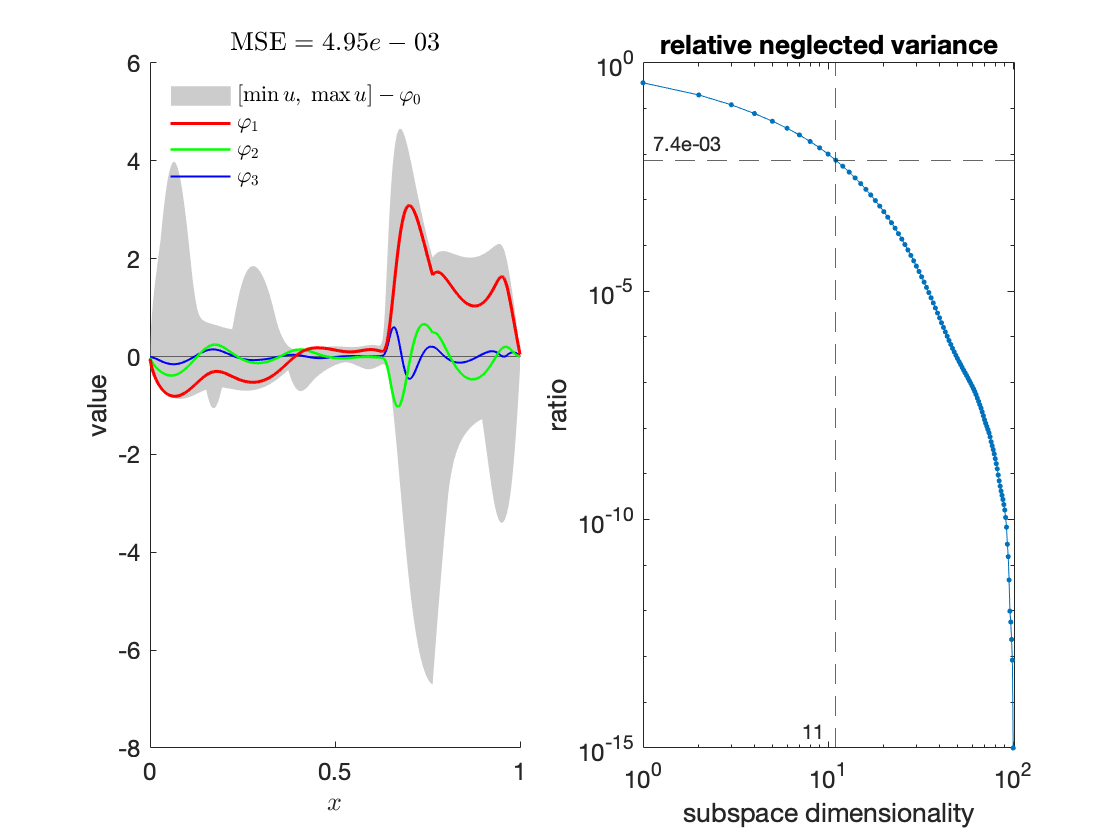

POD = PCA(FOM.X, 1e-2).plotSummary(figure(),'FontSize',12, 'layout','separate');

#### Simulation

ng_param = struct(...
    'iters'    , 10,...
    'iters_min', 3,...
    'tol'      , 0,...
    'tol_rel'  , 1e-3,...
    'tol_g'    , 0,...
    'tol_rel_g', 1e-3 ...
    );

ROM_I = makeROM_I('ROM-I', POD.genEncoder());
nlin.gauss = @(x,Res,Jac) newton_gauss(x,Res,Jac, ng_param, POD.genEncoder().decjac);

ROM_I = solveDif(1,Nt,ROM_I,nlin.gauss);
ROM_I.X = POD.decode(ROM_I.X);

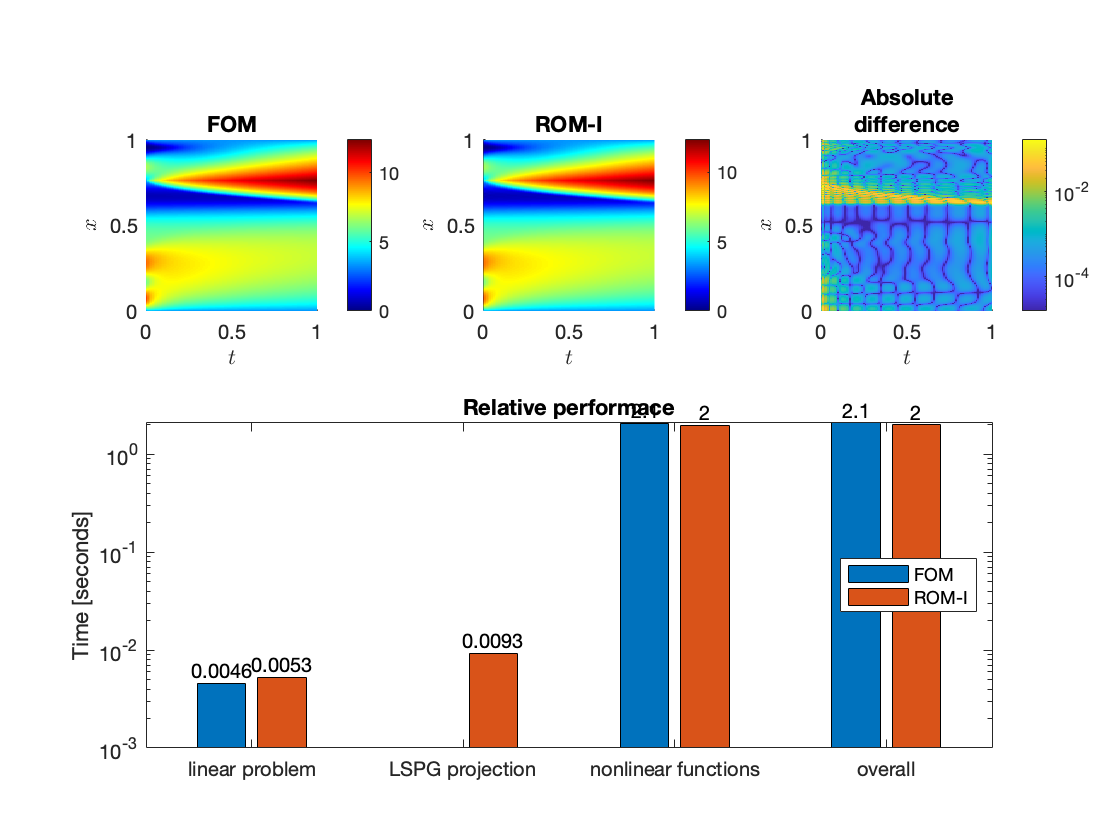

plotComp(figure(),FOM,ROM_I, 10);

### ROM-II

#### Gappy-POD Data

[~,W,Jw,~] = collectSolData(ROM_I);


$$g(u)$$


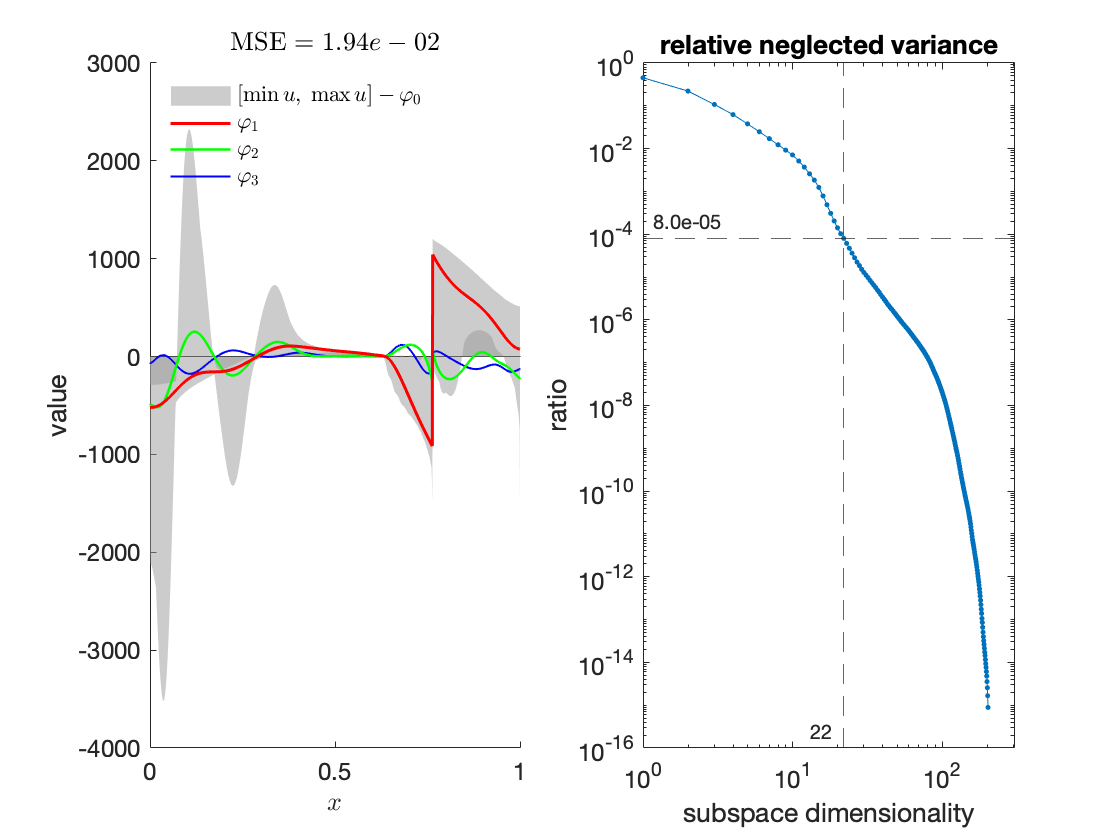

POD_g = PCA(W, 1e-4,'init',zeros(Nx+1,1)).plotSummary(figure(),'FontSize',12, 'layout','separate');


$$g'(u)$$


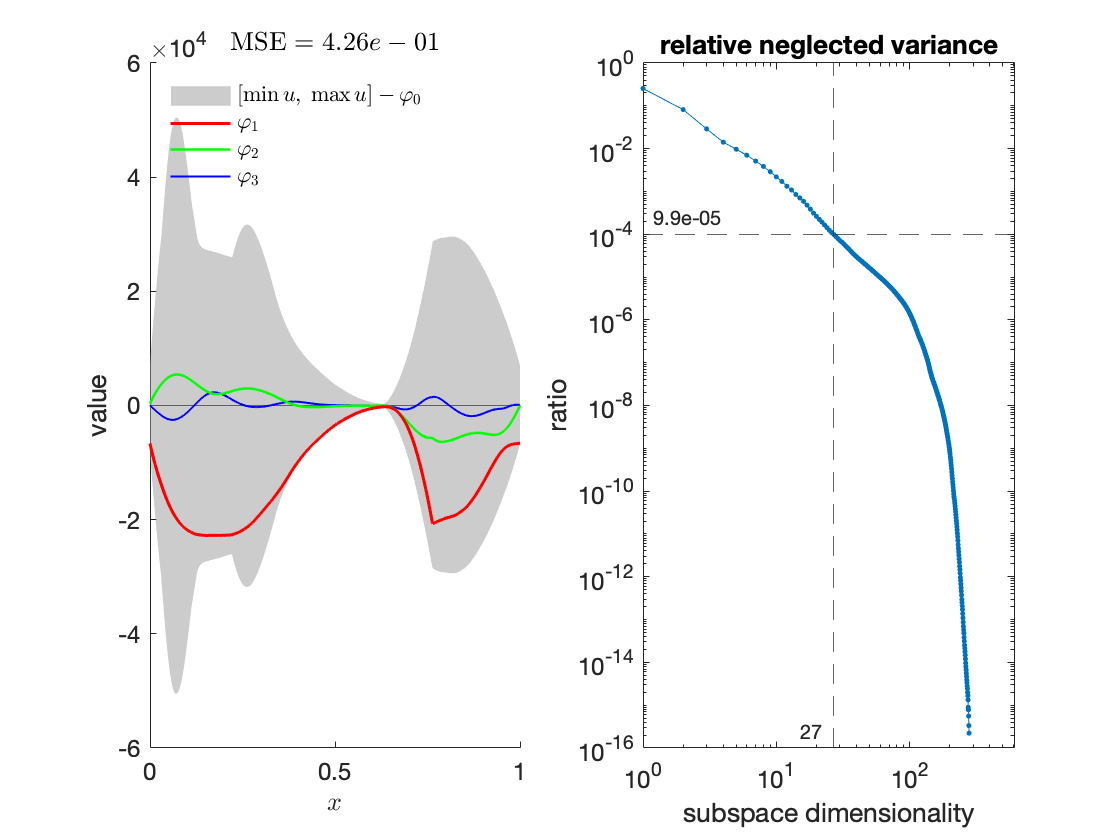

POD_jg = PCA(Jw, 1e-4,'init',zeros(Nx+1,1)).plotSummary(figure(),'FontSize',12, 'layout','separate');

#### Gappy measurement mask

idx = POD_g.calcGreedy(POD_g.npc());
idx_res = idx;
idx = [idx,POD_jg.calcGreedy(POD_jg.npc())];
idx = [idx,1,Nx+1,Q.pos];
idx = unique(idx);

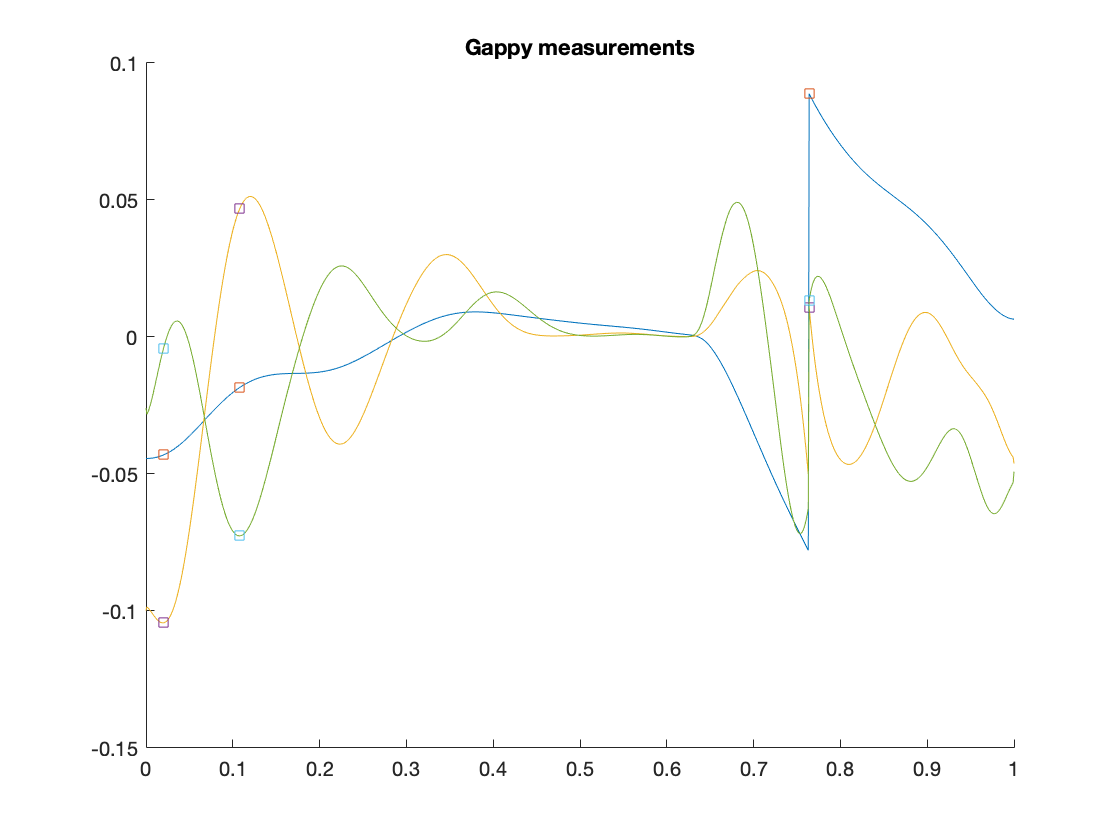

coords = linspace(0,1,Nx+1);
Npc = 3;
idx_disp = idx_res(1:Npc);
figure;
hold on;
for npc = 1:Npc
plot(coords,POD_g.u(:,npc));
scatter(coords(idx_disp),POD_g.u(idx_disp,npc),'s');
end
title('Gappy measurements');
hold off;

POD_g = POD_g.buildGappy(idx);
POD_jg = POD_jg.buildGappy(idx);

#### Simulation

ROM_II = makeROM_II('ROM-II',POD.genEncoder(),POD_g.genNFA(),POD_jg.genNFA());
ROM_II = solveDif(1,Nt,ROM_II,nlin.gauss);
ROM_II.X = POD.decode(ROM_II.X);

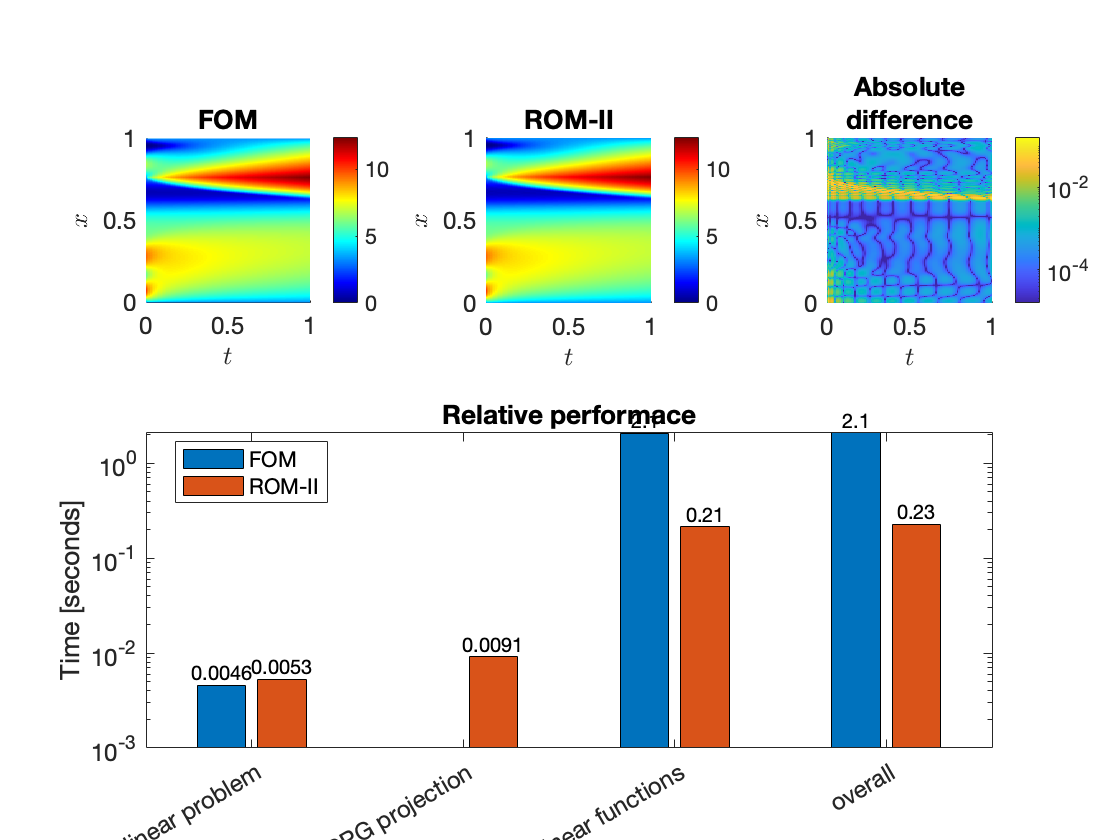

plotComp(figure(),FOM,ROM_II, 12);

### Generalizing ability

#### High

Train cases

logN = 1;
N =3^logN+1;

X = lhsdesign(N,3,'Smooth','on');
xnames = {'BC';'Source Intensity';'Diffusion Scale'};
X(:,1:2) = 10*X(:,1:2);
X(:,3) = 1e-4 + 1e-3*X(:,3);

Test case

delta = X(2:end,:);
delta = delta - X(1,:);
W = rand(N-1,1);
W = W / sum(W);
x_test=mean(delta .* W) + X(1,:);

Plot cases

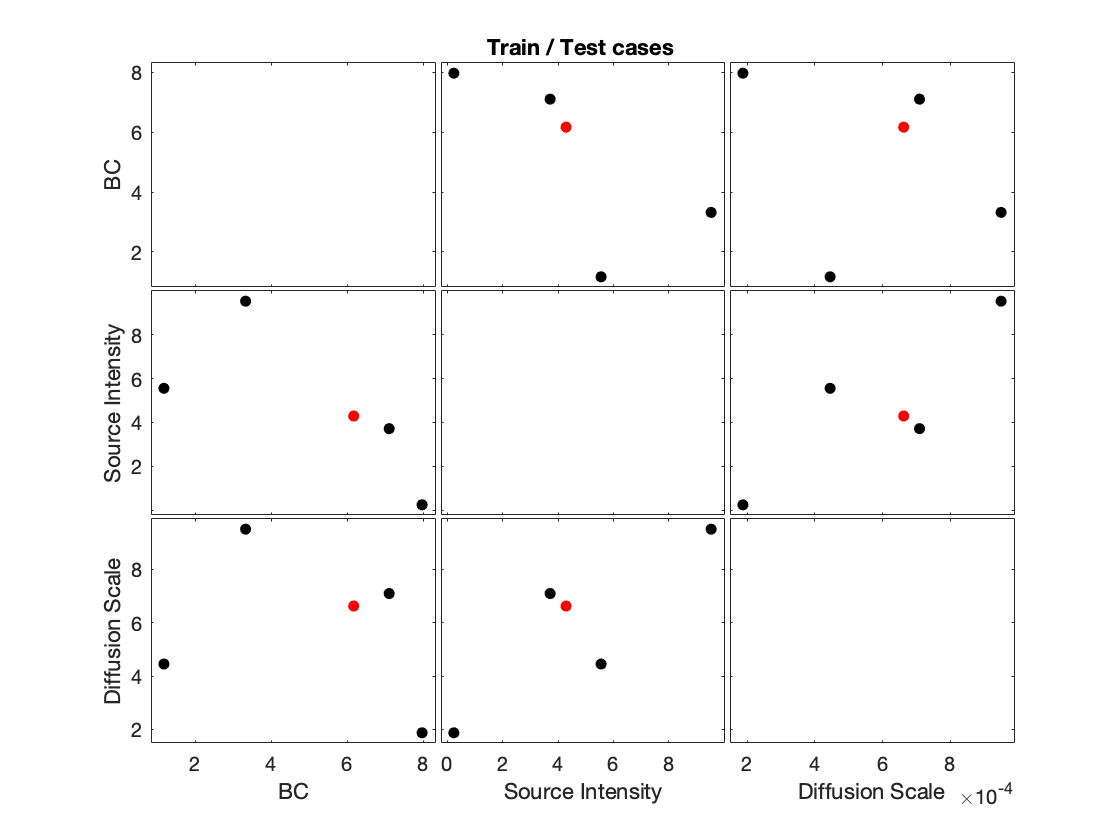

groups = split(num2str(1:N));
groups{end+1} = 'Test case';
fsamples = gplotmatrix(figure(),[X;x_test],[],groups,'kkkkr','.',[],'off','none',xnames);
title('Train / Test cases');

Train ROM-II

- Collect data

X_train = [];
W_train = [];
J_train = [];
for i = 1:size(X,1)
    bc_i = X(i,1);
    BC_i = genBC(1,repmat(bc_i,1,2));
    
    D_i.val = K ./ K(1) .* X(i,3);
    D_i.model = calcG;
    
    Q_i.pos = round(Nx*q_pos); 
    Q_i.val = sparse(Q_i.pos,1,X(i,2),Nx,1);
    
    param_i = genParam(D_i,BC_i,Q_i);
    
    TRAIN = genProblem('TRAIN',Nx,param_i,x0);
    TRAIN = solveDif(1,Nt,TRAIN, nlin_newton);
    [X_i,W_i,J_i,~] = collectSolData(TRAIN);
    X_train = [X_train,X_i];
    W_train = [W_train,W_i];
    J_train = [J_train,J_i];
end

- Train POD

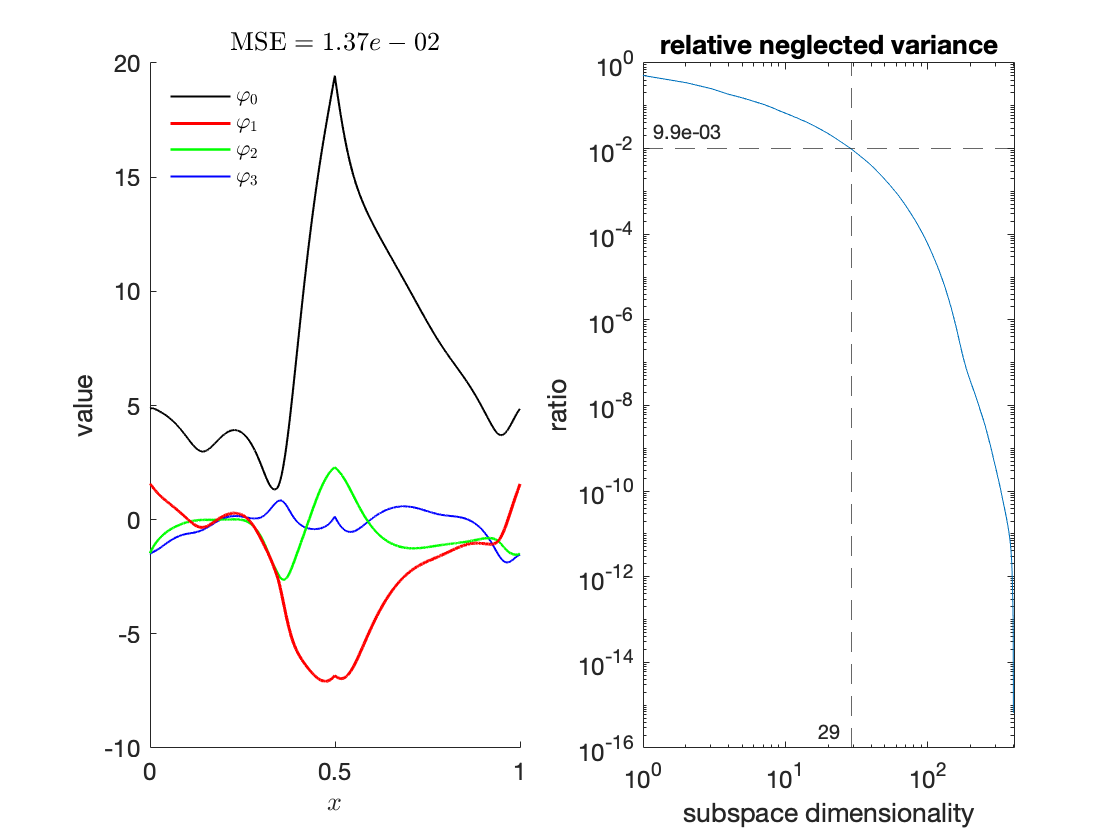

POD = PCA(X_train, 1e-2).plotSummary(figure(),'FontSize',12, 'layout','separate');

- Train Gappy-POD

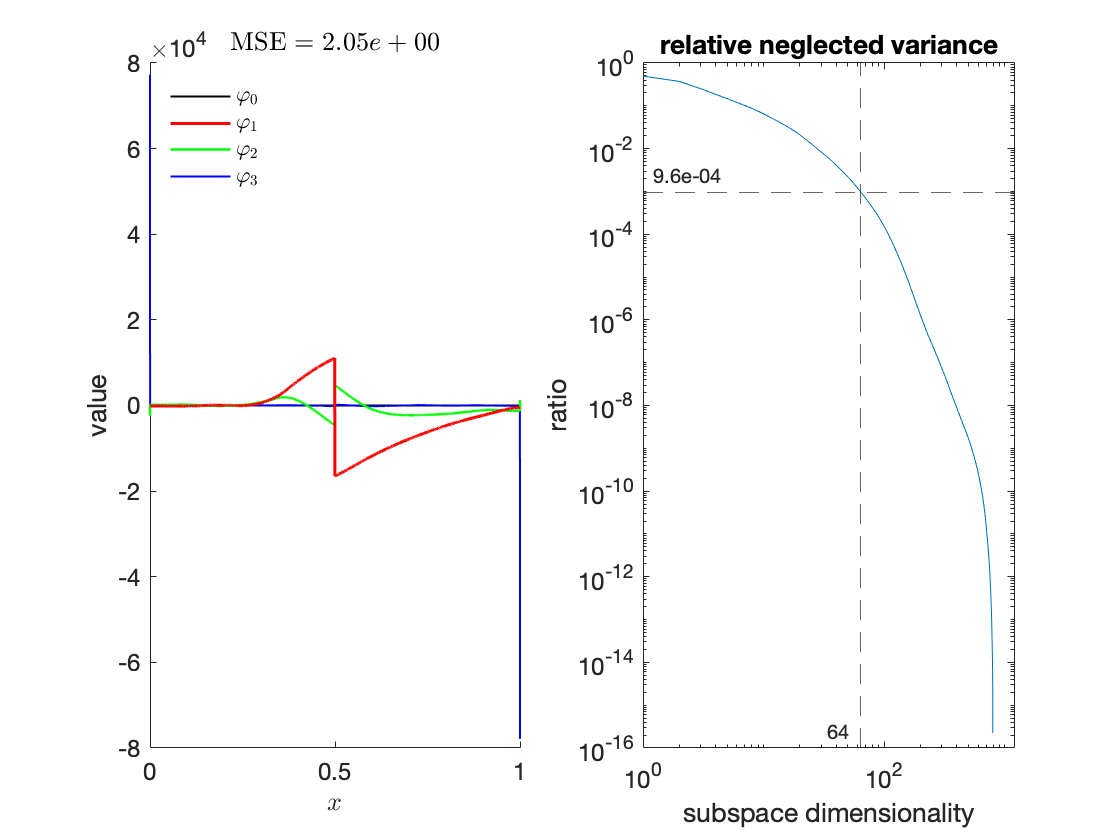

POD_g = PCA(W_train, 1e-3,'init',zeros(Nx+1,1)).plotSummary(figure(),'FontSize',12, 'layout','separate');

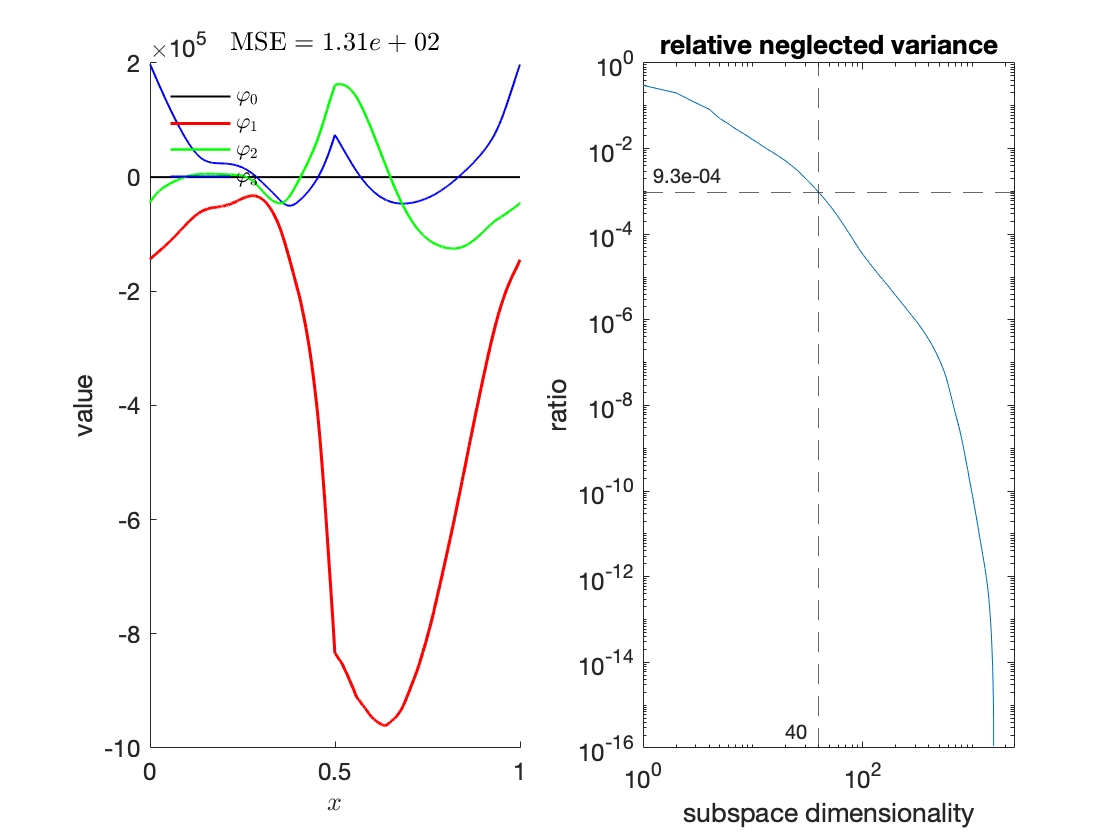

POD_dg = PCA(J_train, 1e-3,'init',zeros(Nx+1,1)).plotSummary(figure(),'FontSize',12, 'layout','separate');

gappy_idx = POD_g.calcGreedy(POD_g.npc());
gappy_idx = [gappy_idx,POD_dg.calcGreedy(POD_dg.npc())];
gappy_idx = [gappy_idx,1,Nx+1,Q.pos];
gappy_idx = unique(gappy_idx);

POD_g = POD_g.buildGappy(gappy_idx);
POD_dg = POD_dg.buildGappy(gappy_idx);

Solve test case

bc_test= x_test(1);
BC_test = genBC(1,repmat(bc_test,1,2));

Q_test.pos = round(Nx*q_pos); 
Q_test.val = sparse(Q_test.pos,1,x_test(2),Nx,1);

D_test.val = K ./ K(1) .* x_test(3);
D_test.model = calcG;
    
param_test = genParam(D_test,BC_test,Q_test);

- FOM as reference

REF = genProblem('REFERENCE',Nx,param_test,x0);
REF = solveDif(1,Nt,REF, nlin_newton);

- ROM-II

TEST = genProblem('TEST',Nx,param_test,x0,POD.genEncoder(),POD_g.genNFA(),POD_dg.genNFA());
nlin_test = @(x,Res,Jac) newton_gauss(x,Res,Jac, ng_param, POD.genEncoder().decjac);
TEST = solveDif(1,Nt,TEST, nlin_test);
TEST.X = POD.decode(TEST.X);

Plot comparison

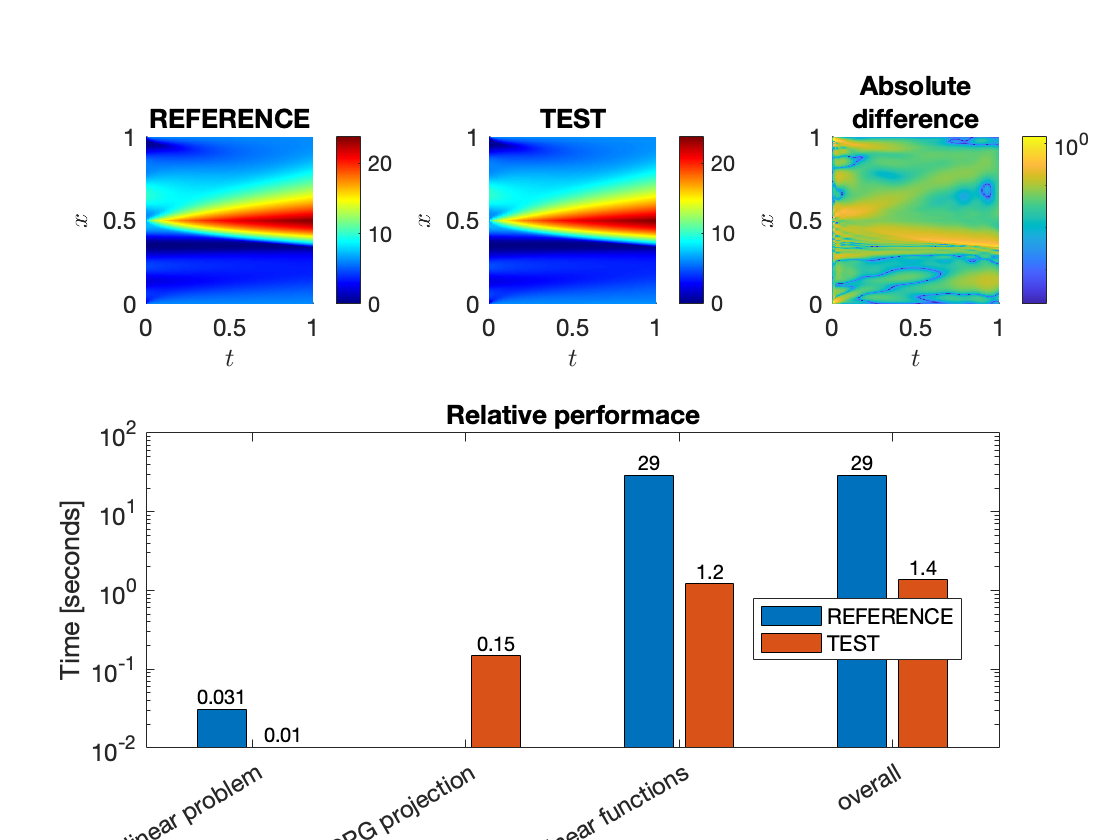

plotComp(figure(),REF,TEST, 12);

#### Low

Train using singe FOM case

Test deviated by a single cell

Test distorted $\kappa$

## Method 1

### POD basis for different x_q

### Domain decomposition and mapping

### Zero-order approach

### Domain-wise POD performance